Define 

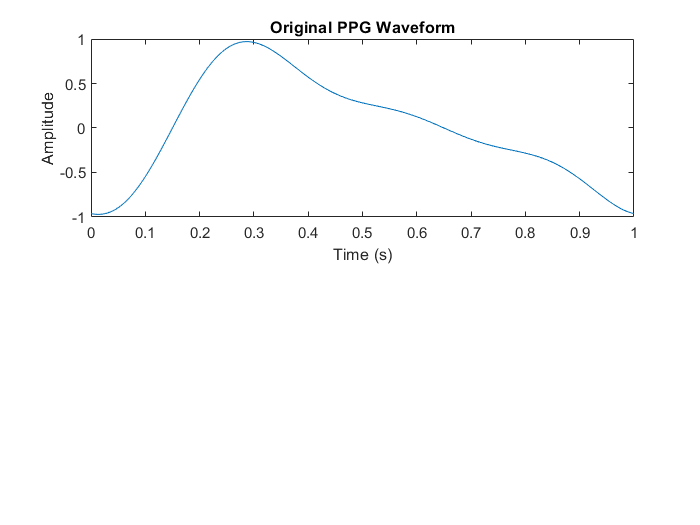


% Sample PPG data (replace this with your actual PPG data)
fs = 200;  % Sampling rate (in Hz)
t = 0:1/fs:1;  % Time vector (replace 10 with the duration of your PPG signal)
ppg_data = (sin(2*pi*1*(t+0.85)) + 0.5*sin(2*pi*2*(t+0.85)) + 0.2*sin(2*pi*3*(t+0.85)))/1.4;

% Plot the original PPG waveform
figure;
subplot(2,1,1);
plot(t, ppg_data);
title('Original PPG Waveform');
xlabel('Time (s)');
ylabel('Amplitude');

% path = '/media/biyon/New Volume/OneDrive - University of Moratuwa/Volume D/FYP/Simulation/Banana/pwdb_data.mat'; 
path = 'D:\OneDrive - University of Moratuwa\Volume D\FYP\Simulation\Banana\pwdb_data.mat';
load(path);

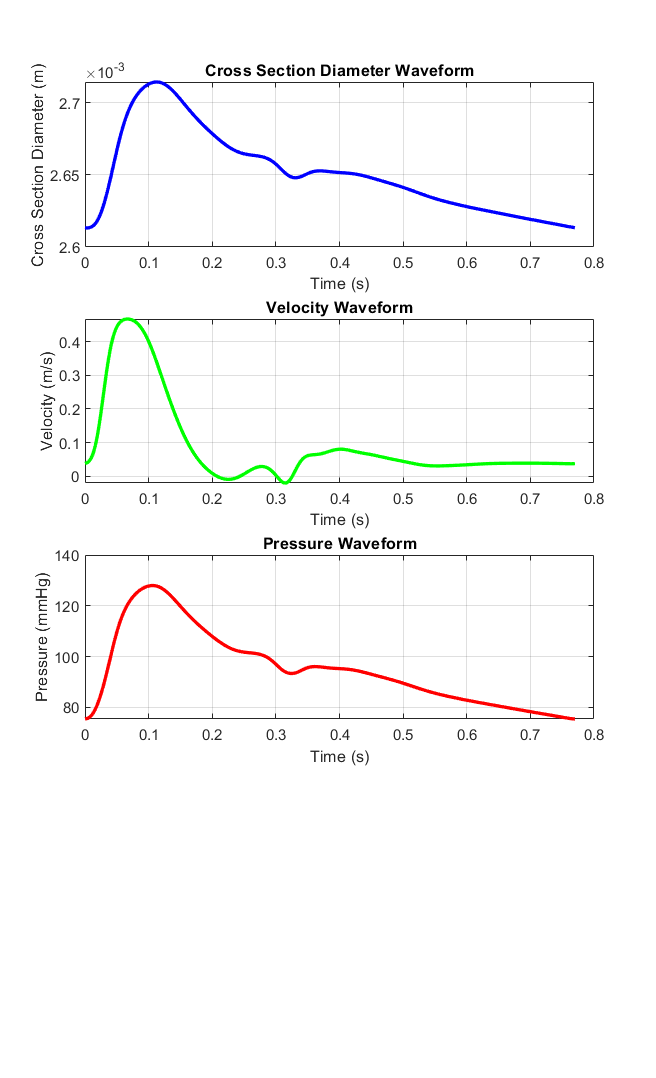


patient = 40;
cross_section = cell2mat(data.waves.A_Radial(patient));
velocity = cell2mat(data.waves.U_Radial(patient));
pressure = cell2mat(data.waves.P_Radial(patient));
PPG = cell2mat(data.waves.PPG_Radial(patient));

Diameter = sqrt((4/pi).*cross_section);

% Assuming you have the sampling frequency (fs) available
fs = data.waves.fs;

% Calculate time vector based on the number of samples and sampling frequency
num_samples = length(pressure);
time = (0:num_samples-1) / fs;

% Plotting the waveforms
figure;

subplot(4,1,1);
plot(time, Diameter, 'b', 'LineWidth', 2);
title('Cross Section Diameter Waveform');
xlabel('Time (s)');
ylabel('Cross Section Diameter (m)');
grid on;

subplot(4,1,2);
plot(time, velocity, 'g', 'LineWidth', 2);
title('Velocity Waveform');
xlabel('Time (s)');
ylabel('Velocity (m/s)');
grid on;

subplot(4,1,3);
plot(time, pressure, 'r', 'LineWidth', 2);
title('Pressure Waveform');
xlabel('Time (s)');
ylabel('Pressure (mmHg)');
grid on;
pos = get(gcf, 'Position');
set(gcf, 'Position',pos+[0 -500 0 500])

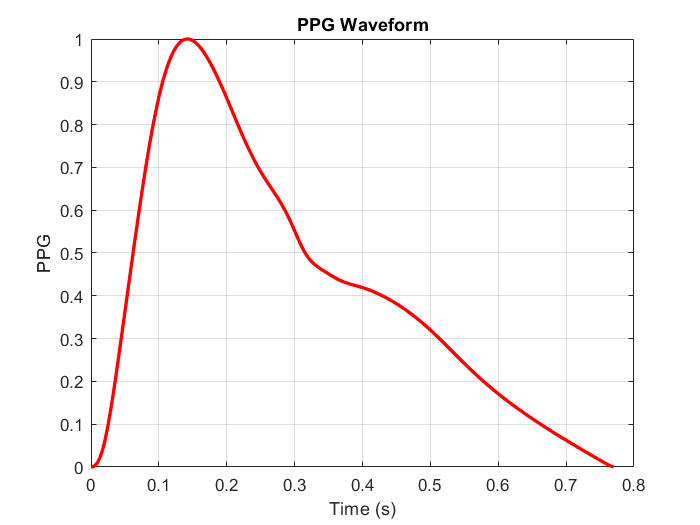


figure;
plot(time, PPG, 'r', 'LineWidth', 2);
title('PPG Waveform');
xlabel('Time (s)');
ylabel('PPG');
grid on;

A = pi*((2.56/2000)^2)

A = 5.1472e-06

m_d =  1613;
k = (10^-6)/(A*60) 

k = 0.0032

Qc =  328*k

Qc = 1.0621

Q = 0:0.1*k:190*k

Q =          0    0.0003    0.0006    0.0010    0.0013    0.0016    0.0019    0.0023    0.0026    0.0029    0.0032    0.0036    0.0039    0.0042    0.0045    0.0049    0.0052    0.0055    0.0058    0.0062    0.0065    0.0068    0.0071    0.0074    0.0078    0.0081    0.0084    0.0087    0.0091    0.0094    0.0097    0.0100    0.0104    0.0107    0.0110    0.0113    0.0117    0.0120    0.0123    0.0126    0.0130    0.0133    0.0136    0.0139    0.0142    0.0146    0.0149    0.0152    0.0155    0.0159


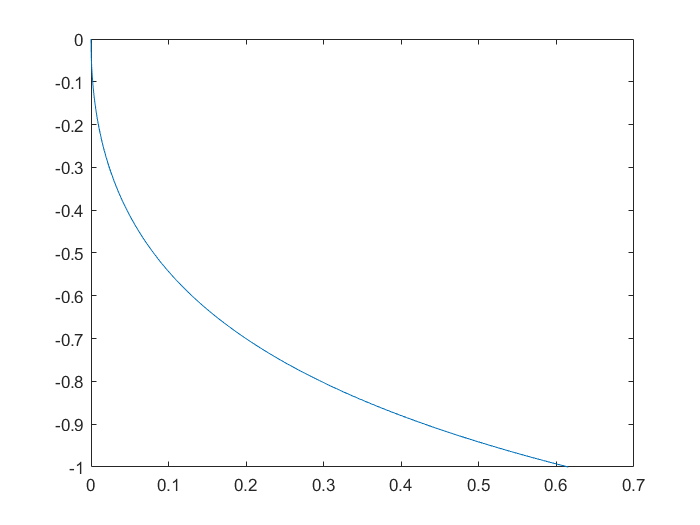

y = -m_d.*(sqrt(Q./Qc)./(1+sqrt(Q./Qc)));
norm_y =(y./max(-y));
figure
plot(Q,norm_y)

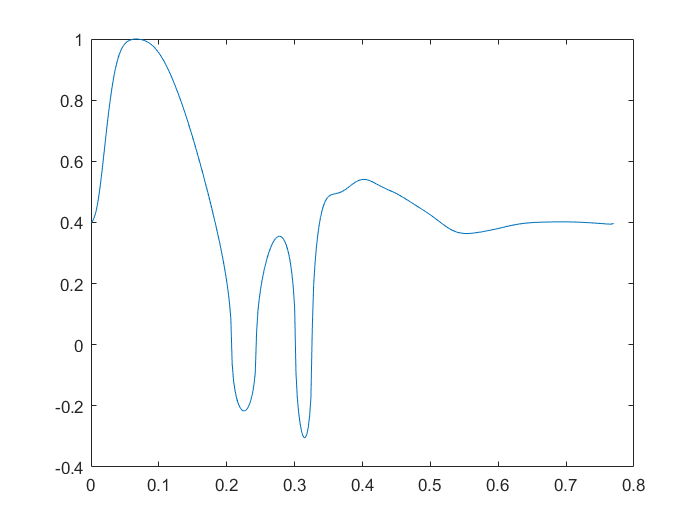

Q = velocity;
y = sign(Q)*m_d.*(sqrt(abs(Q./Qc))./(1+sqrt(abs(Q./Qc))));
norm_y =  y./max(y);
figure
plot(time,norm_y)

nd = 0.6875;
na = 0.3125;
tud = 0.39;
tua = 1.78;
delta = nd.*exp(-time./tud) + na.*exp(-time./tua)

delta =     1.0000    0.9961    0.9923    0.9885    0.9846    0.9808    0.9771    0.9733    0.9696    0.9658    0.9621    0.9585    0.9548    0.9511    0.9475    0.9439    0.9403    0.9367    0.9331    0.9296    0.9260    0.9225    0.9190    0.9155    0.9121    0.9086    0.9052    0.9018    0.8984    0.8950    0.8916    0.8883    0.8849    0.8816    0.8783    0.8750    0.8717    0.8685    0.8652    0.8620    0.8588    0.8556    0.8524    0.8492    0.8461    0.8429    0.8398    0.8367    0.8336    0.8305


norm_delta = delta./sum(delta)

norm_delta =     0.0047    0.0047    0.0046    0.0046    0.0046    0.0046    0.0046    0.0046    0.0045    0.0045    0.0045    0.0045    0.0045    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0043    0.0043    0.0043    0.0043    0.0043    0.0043    0.0043    0.0042    0.0042    0.0042    0.0042    0.0042    0.0042    0.0041    0.0041    0.0041    0.0041    0.0041    0.0041    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0039    0.0039    0.0039    0.0039    0.0039


ab = conv(norm_y,norm_delta,'same')

ab =     0.2784
    0.2799
    0.2814
    0.2829
    0.2845
    0.2860
    0.2876
    0.2891
    0.2906
    0.2922


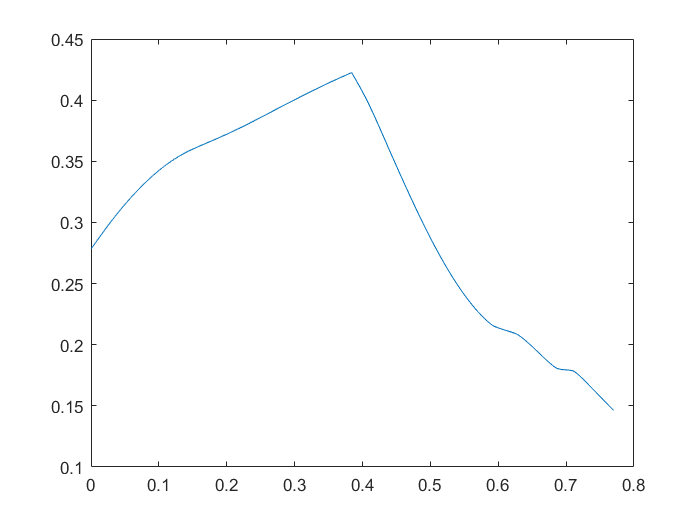

figure
plot(time,ab)

parameters = num2cell(cat(2, Diameter, pressure, ab),2)

parameters = 386×1 cell array
    {[0.0026 75.3971 0.2784]}
    {[0.0026 75.4860 0.2799]}
    {[0.0026 75.6522 0.2814]}
    {[0.0026 75.9151 0.2829]}
    {[0.0026 76.2927 0.2845]}
    {[0.0026 76.7979 0.2860]}
    {[0.0026 77.4433 0.2876]}
    {[0.0026 78.2342 0.2891]}
    {[0.0026 79.1736 0.2906]}
    {[0.0026 80.2600 0.2922]}
    {[0.0026 81.4882 0.2937]}
    {[0.0026 82.8529 0.2952]}
    {[0.0026 84.3466 0.2967]}
    {[0.0026 85.9610 0.2982]}
    {[0.0026 87.6887 0.2996]}
    {[0.0026 89.5191 0.3011]}


parameters{1}(3)

ans = 0.2784

nPhotonsCollected_values = zeros(size(time));

% Create a progress bar
h = waitbar(0, 'Processing...');

% Loop over each pL1 value
for i = 1:length(time)
    % Update the progress bar
    waitbar(i / length(time), h, sprintf('Processing... %d%%', round(i / length(time) * 100)));
    
    % Your existing code
    nPhotonsCollected_values(i) = model(parameters{i});
end 

% Close the progress bar
close(h);

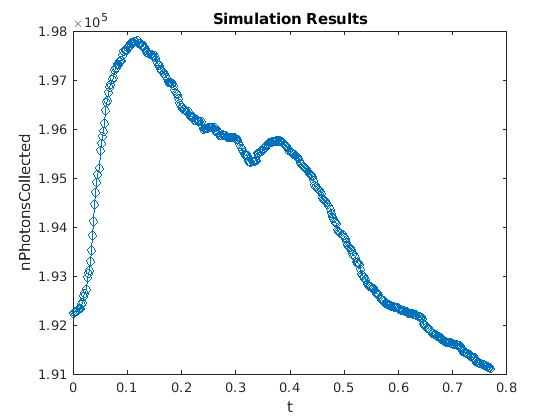

% Plot the nPhotonsCollected values against pL1
figure;
plot(time, nPhotonsCollected_values, '-o');
xlabel('t');
ylabel('nPhotonsCollected');
title('Simulation Results');